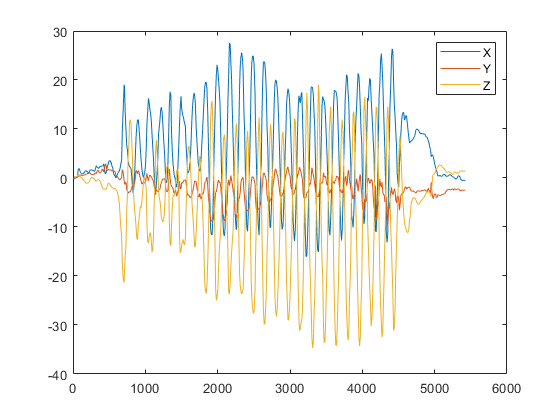

A_X2 = A_X - A_X(1,1);
A_Y2 = A_Y - A_Y(1,1);
A_Z2 = A_Z - A_Z(1,1);
plot(A_Milliseconds,A_X2)
hold on
plot(A_Milliseconds,A_Y2)
plot(A_Milliseconds,A_Z2)
legend('X','Y','Z')
hold off

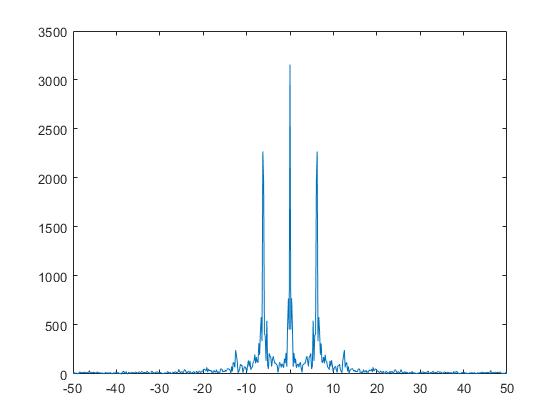

Fs = 100;
N = 543;
frequencies_shifted = (linspace(-pi, pi-2/N*pi, N) + pi/N*mod(N,2)) * Fs / (2*pi);
plot(frequencies_shifted,abs(fftshift(fft(A_X2))))

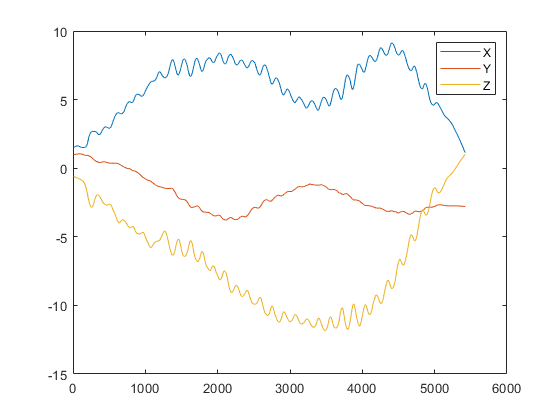

AXFilt = movmean(A_X2,100);
AYFilt = movmean(A_Y2,100);
AZFilt = movmean(A_Z2,100);
plot(A_Milliseconds,AXFilt)
hold on
plot(A_Milliseconds,AYFilt)
plot(A_Milliseconds,AZFilt)
legend('X','Y','Z')
hold off

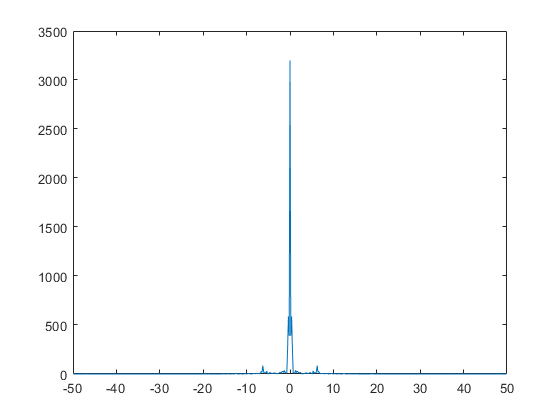

plot(frequencies_shifted,abs(fftshift(fft(AXFilt))))

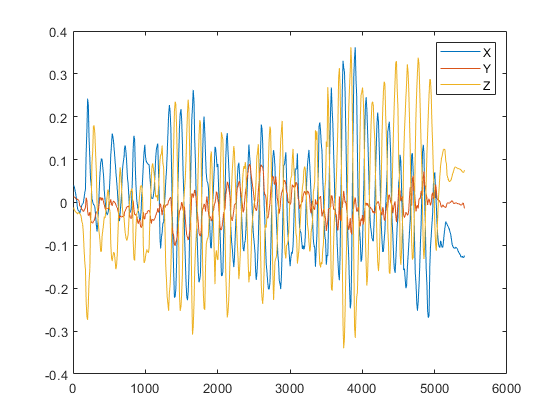

VX = diff(AXFilt,1);
VY = diff(AYFilt,1);
VZ = diff(AZFilt,1);
plot(A_Milliseconds(1:end-1),VX)
hold on
plot(A_Milliseconds(1:end-1),VY)
plot(A_Milliseconds(1:end-1),VZ)
legend('X','Y','Z')
hold off

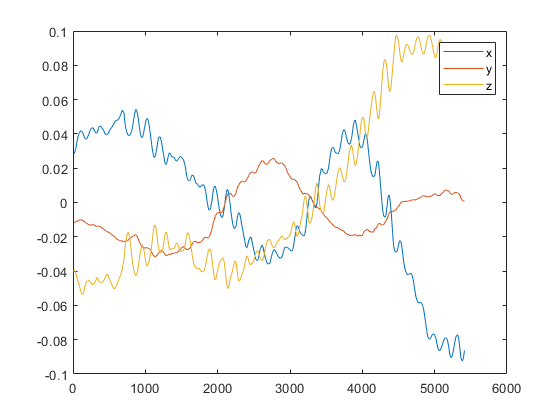

vxf = movmean(VX,100);
vyf = movmean(VY,100);
vzf = movmean(VZ,100);
plot(A_Milliseconds(1:end-1),vxf)
hold on
plot(A_Milliseconds(1:end-1),vyf)
plot(A_Milliseconds(1:end-1),vzf)
legend('x','y','z')
hold off

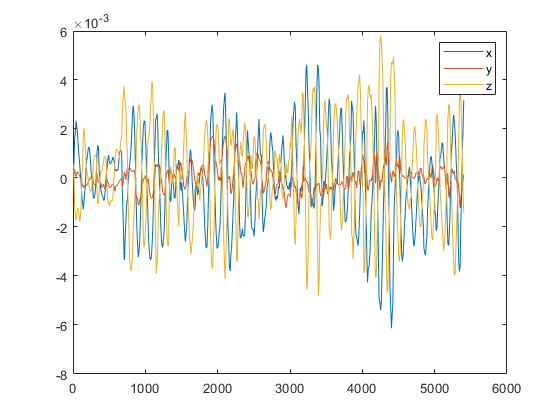

x = diff(vxf,1);
y = diff(vyf,1);
z = diff(vzf,1);
plot(A_Milliseconds(1:end-2),x)
hold on
plot(A_Milliseconds(1:end-2),y)
plot(A_Milliseconds(1:end-2),z)
legend('x','y','z')
hold off

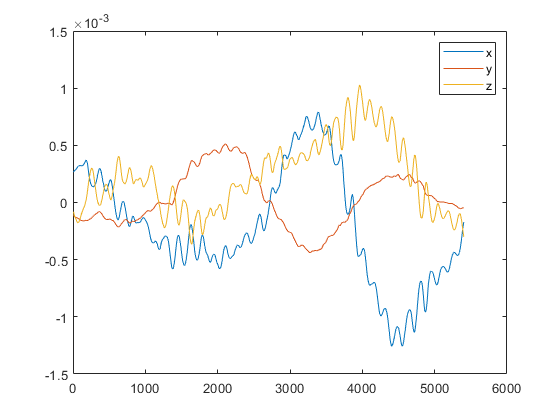

xf = movmean(x,100);
yf = movmean(y,100);
zf = movmean(z,100);
plot(A_Milliseconds(1:end-2),xf)
hold on
plot(A_Milliseconds(1:end-2),yf)
plot(A_Milliseconds(1:end-2),zf)
legend('x','y','z')
hold off

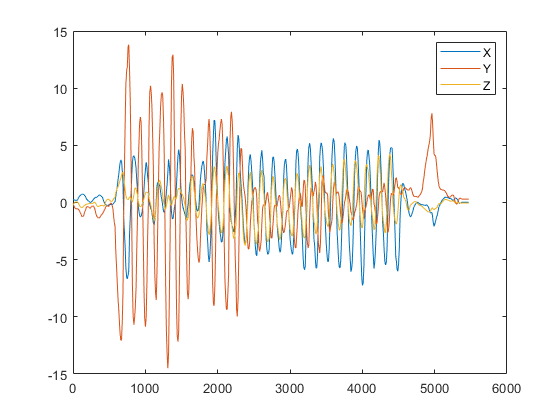

plot(G_Milliseconds,G_X)
hold on
plot(G_Milliseconds,G_Y)
plot(G_Milliseconds,G_Z)
legend('X','Y','Z')
hold off

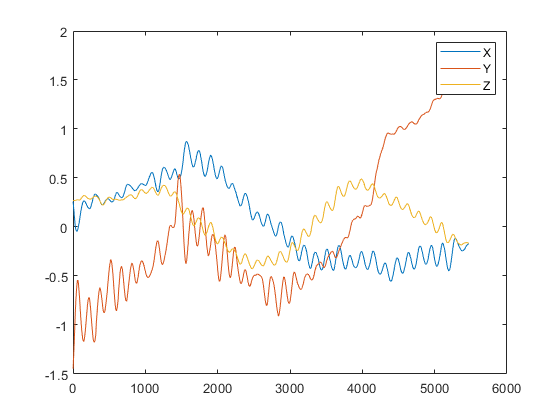

gxf = movmean(G_X,150);
gyf = movmean(G_Y,150);
gzf = movmean(G_Z,150);
plot(G_Milliseconds,gxf)
hold on
plot(G_Milliseconds,gyf)
plot(G_Milliseconds,gzf)
legend('X','Y','Z')
hold off

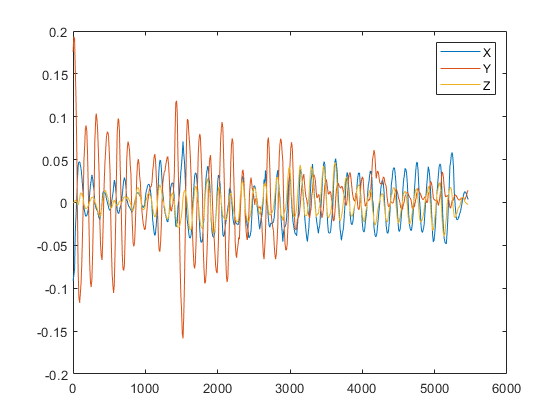

xor = diff(gxf,1);
yor = diff(gyf,1);
zor = diff(gzf,1);
plot(G_Milliseconds(1:end-1),xor)
hold on
plot(G_Milliseconds(1:end-1),yor)
plot(G_Milliseconds(1:end-1),zor)
legend('X','Y','Z')
hold off

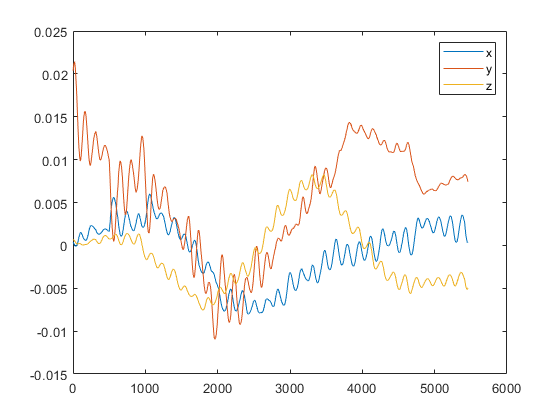

xorf = movmean(xor,100);
yorf = movmean(yor,100);
zorf = movmean(zor,100);
plot(G_Milliseconds(1:end-1),xorf)
hold on
plot(G_Milliseconds(1:end-1),yorf)
plot(G_Milliseconds(1:end-1),zorf)
legend('x','y','z')
hold off